# Reto F3001C

Max Eduardo Garcia Esquivel - A01236070.

   %Code Variables
%Sizes
sXs = [1000,930,475,405];
sYs = [325,235,955,730];

%Paths
SuperiorPath = "./../Phase4V2/Sweeps/Matlab/";
FundamentalPath = "./../Phase3/Sweeps/Matlab/";

%Modes
Superior = "Waveguide%i_%i_532_Mode%i";
Fundamental = "Waveguide%i_%i_1596";
ModesSup = [15,9,19,12];

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale')

## Waveguide selector:

sel = 3;
nmodes = ModesSup(sel);
mode = 15;
disp("Selected waveguide:")

Selected waveguide:


disp("   Size: "+num2str(sXs(sel))+"x"+num2str(sYs(sel)));

   Size: 475x955


disp("   Mode: "+num2str(mode));

   Mode: 15


## Waveguide Summary:

disp("Waveguide: "+num2str(sXs(sel))+"x"+num2str(sXs(sel))+", mode: "+num2str(ModesSup(sel)));

Waveguide: 475x475, mode: 19


### Fundamental Mode Data (1596nm):

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 1.53-1.596


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 1181049869.7706-1231997119.0548


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgFundamental.nefflStr);

0.000017319307674958947198444806*l.^30-0.000136783674043061947295241154*l.^29+0.000295947599398755528156412797*l.^28+0.000150202542880631097427582277*l.^27-0.000906798222071632676472008328*l.^26+0.000169573591986222314831334046*l.^25-0.001881841206221113952518075862*l.^24+0.007674134487335452364797916402*l.^23+0.000754648791832529465713197414*l.^22-0.014968201012707106623000896661*l.^21+0.008329761877042856504926859884*l.^20-0.033771278559173424638206739701*l.^19+0.051745338024580346536485109254*l.^18+0.077950493413985341706329279532*l.^17-0.178537839826608896176551866120*l.^16+0.059380499095359515204783917852*l.^15+0.118424191009439405686265445183*l.^14-0.334978957355768602877077455560*l.^13+1.027788088418601031293064806960*l.^12-2.299647710601314454237353857025*l.^11+3.386732681563251468048747483408*l.^10-4.796427624083937857335513399448*l.^9+2.980311910000663200293047339073*l.^8+8.751265264282766409564828791190*l.^7-21.993288863644107067329969140701*l.^6+33.6630699858250679312732245

disp("Function neff(ω)");

Function neff(ω)


disp(wgFundamental.neffwStr);

1.057981373733877631075077401994e-271*w.^30-4.876575195987541549652917935234e-262*w.^29+7.275338059549487537387861160671e-253*w.^28-8.114141995883427553673007544339e-244*w.^27+1.974311751315298732121579202997e-234*w.^26-1.745501063688897161148555270670e-225*w.^25-1.755334875010731352498567836116e-216*w.^24+1.956293397266707881902828590206e-207*w.^23-4.786824394855794162395672131440e-199*w.^22+2.607487800940617839801720612747e-189*w.^21-3.532158650278968704479550593286e-180*w.^20+8.018390453769734840763288914621e-171*w.^19-1.050922745553905761277645635758e-161*w.^18+7.043406735132534564533847751959e-153*w.^17-1.057189006576952030319417374640e-143*w.^16+8.026897346734778237021190637934e-135*w.^15-1.097344793805301551148469036618e-125*w.^14+1.183963698317498519818939342610e-116*w.^13-1.223967693943213057413875742154e-107*w.^12+5.597863564766401175014053355252e-98*w.^11+2.256266598631080367186670808380e-90*w.^10-1.142123058806093848696804422482e-79*w.^9+5.050299339348076613595038921917e-71

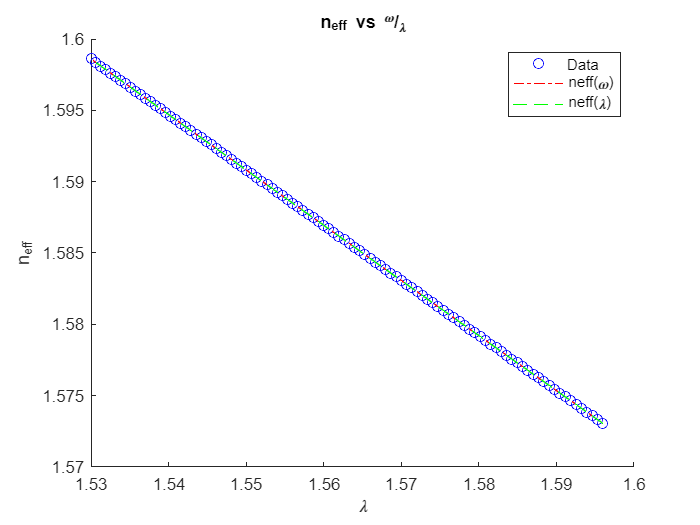

figure;
hold on
title("n_{eff} vs ^{\omega}/_{\lambda}");
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgFundamental.kwStr);

w.*(1.057981373733877631075077401994e-271*w.^30-4.876575195987541549652917935234e-262*w.^29+7.275338059549487537387861160671e-253*w.^28-8.114141995883427553673007544339e-244*w.^27+1.974311751315298732121579202997e-234*w.^26-1.745501063688897161148555270670e-225*w.^25-1.755334875010731352498567836116e-216*w.^24+1.956293397266707881902828590206e-207*w.^23-4.786824394855794162395672131440e-199*w.^22+2.607487800940617839801720612747e-189*w.^21-3.532158650278968704479550593286e-180*w.^20+8.018390453769734840763288914621e-171*w.^19-1.050922745553905761277645635758e-161*w.^18+7.043406735132534564533847751959e-153*w.^17-1.057189006576952030319417374640e-143*w.^16+8.026897346734778237021190637934e-135*w.^15-1.097344793805301551148469036618e-125*w.^14+1.183963698317498519818939342610e-116*w.^13-1.223967693943213057413875742154e-107*w.^12+5.597863564766401175014053355252e-98*w.^11+2.256266598631080367186670808380e-90*w.^10-1.142123058806093848696804422482e-79*w.^9+5.050299339348076613595038921917

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgFundamental.dkwdwStr);

(1.057981373733877631075077401994e-271*w.^30*(31)-4.876575195987541549652917935234e-262*w.^29*(30)+7.275338059549487537387861160671e-253*w.^28*(29)-8.114141995883427553673007544339e-244*w.^27*(28)+1.974311751315298732121579202997e-234*w.^26*(27)-1.745501063688897161148555270670e-225*w.^25*(26)-1.755334875010731352498567836116e-216*w.^24*(25)+1.956293397266707881902828590206e-207*w.^23*(24)-4.786824394855794162395672131440e-199*w.^22*(23)+2.607487800940617839801720612747e-189*w.^21*(22)-3.532158650278968704479550593286e-180*w.^20*(21)+8.018390453769734840763288914621e-171*w.^19*(20)-1.050922745553905761277645635758e-161*w.^18*(19)+7.043406735132534564533847751959e-153*w.^17*(18)-1.057189006576952030319417374640e-143*w.^16*(17)+8.026897346734778237021190637934e-135*w.^15*(16)-1.097344793805301551148469036618e-125*w.^14*(15)+1.183963698317498519818939342610e-116*w.^13*(14)-1.223967693943213057413875742154e-107*w.^12*(13)+5.597863564766401175014053355252e-98*w.^11*(12)+2.256266598631080367

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgFundamental.vgwStr);

(3*10^8)./(1.057981373733877631075077401994e-271*w.^30*(31)-4.876575195987541549652917935234e-262*w.^29*(30)+7.275338059549487537387861160671e-253*w.^28*(29)-8.114141995883427553673007544339e-244*w.^27*(28)+1.974311751315298732121579202997e-234*w.^26*(27)-1.745501063688897161148555270670e-225*w.^25*(26)-1.755334875010731352498567836116e-216*w.^24*(25)+1.956293397266707881902828590206e-207*w.^23*(24)-4.786824394855794162395672131440e-199*w.^22*(23)+2.607487800940617839801720612747e-189*w.^21*(22)-3.532158650278968704479550593286e-180*w.^20*(21)+8.018390453769734840763288914621e-171*w.^19*(20)-1.050922745553905761277645635758e-161*w.^18*(19)+7.043406735132534564533847751959e-153*w.^17*(18)-1.057189006576952030319417374640e-143*w.^16*(17)+8.026897346734778237021190637934e-135*w.^15*(16)-1.097344793805301551148469036618e-125*w.^14*(15)+1.183963698317498519818939342610e-116*w.^13*(14)-1.223967693943213057413875742154e-107*w.^12*(13)+5.597863564766401175014053355252e-98*w.^11*(12)+2.25626659

disp("Function d2k(ω)/dω:");

Function d2k(ω)/dω:


disp(wgFundamental.d2kwdw2Str);

(1.057981373733877631075077401994e-271*w.^29*(930)-4.876575195987541549652917935234e-262*w.^28*(870)+7.275338059549487537387861160671e-253*w.^27*(812)-8.114141995883427553673007544339e-244*w.^26*(756)+1.974311751315298732121579202997e-234*w.^25*(702)-1.745501063688897161148555270670e-225*w.^24*(650)-1.755334875010731352498567836116e-216*w.^23*(600)+1.956293397266707881902828590206e-207*w.^22*(552)-4.786824394855794162395672131440e-199*w.^21*(506)+2.607487800940617839801720612747e-189*w.^20*(462)-3.532158650278968704479550593286e-180*w.^19*(420)+8.018390453769734840763288914621e-171*w.^18*(380)-1.050922745553905761277645635758e-161*w.^17*(342)+7.043406735132534564533847751959e-153*w.^16*(306)-1.057189006576952030319417374640e-143*w.^15*(272)+8.026897346734778237021190637934e-135*w.^14*(240)-1.097344793805301551148469036618e-125*w.^13*(210)+1.183963698317498519818939342610e-116*w.^12*(182)-1.223967693943213057413875742154e-107*w.^11*(156)+5.597863564766401175014053355252e-98*w.^10*(132)+

disp("Function D(ω):");

Function D(ω):


disp(wgFundamental.DwStr);

-(w.^2/(2*pi*3*10^8)).*((1.057981373733877631075077401994e-271*w.^29*(930)-4.876575195987541549652917935234e-262*w.^28*(870)+7.275338059549487537387861160671e-253*w.^27*(812)-8.114141995883427553673007544339e-244*w.^26*(756)+1.974311751315298732121579202997e-234*w.^25*(702)-1.745501063688897161148555270670e-225*w.^24*(650)-1.755334875010731352498567836116e-216*w.^23*(600)+1.956293397266707881902828590206e-207*w.^22*(552)-4.786824394855794162395672131440e-199*w.^21*(506)+2.607487800940617839801720612747e-189*w.^20*(462)-3.532158650278968704479550593286e-180*w.^19*(420)+8.018390453769734840763288914621e-171*w.^18*(380)-1.050922745553905761277645635758e-161*w.^17*(342)+7.043406735132534564533847751959e-153*w.^16*(306)-1.057189006576952030319417374640e-143*w.^15*(272)+8.026897346734778237021190637934e-135*w.^14*(240)-1.097344793805301551148469036618e-125*w.^13*(210)+1.183963698317498519818939342610e-116*w.^12*(182)-1.223967693943213057413875742154e-107*w.^11*(156)+5.59786356476640117501405

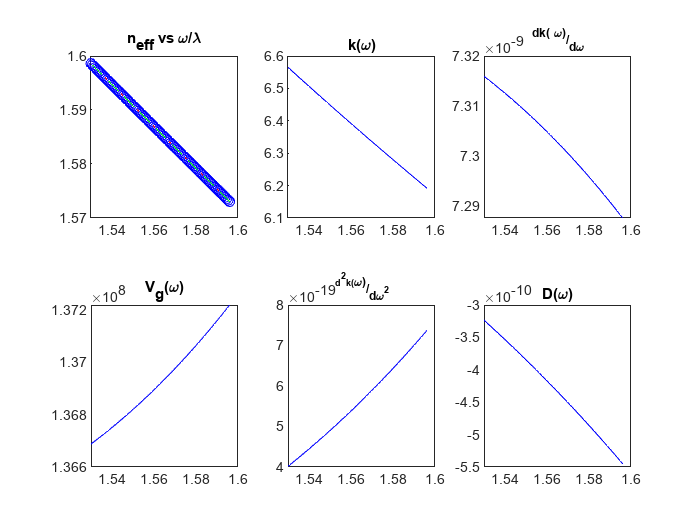

subplot(2,3,1);
plot(l,neff,'bo',l,wgFundamental.neffwFun(w),'r-.',l,wgFundamental.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgFundamental.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgFundamental.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgFundamental.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgFundamental.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgFundamental.DwFun(w),'b');
title("D(\omega)");

### Superior Mode Data (530nm):

file = sprintf(Superior,sXs(sel),sYs(sel),ModesSup(sel));
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);
l = wgSuperior.lambdaData;
w = wgSuperior.omegaData;
neff = wgSuperior.neffData;

#### Ranges:

disp("Lambda Ranges: "+num2str(min(l))+"-"+num2str(max(l))+"");

Lambda Ranges: 0.51-0.532


disp("Omega Ranges: "+num2str(min(w))+"-"+num2str(max(w))+"");

Omega Ranges: 3543149609.3118-3695991357.1645


#### Neff vs ω/λ

disp("Function neff(λ):");

Function neff(λ):


disp(wgSuperior.nefflStr);

-31869752176223636.000000000000000000000000000000*l.^30+86060009129982432.000000000000000000000000000000*l.^29-91394175372286544.000000000000000000000000000000*l.^28+53297577580030184.000000000000000000000000000000*l.^27-18490980250246096.000000000000000000000000000000*l.^26-5640649453551884.000000000000000000000000000000*l.^25+11004418617416882.000000000000000000000000000000*l.^24-1326077058041586.750000000000000000000000000000*l.^23-2626204348318588.000000000000000000000000000000*l.^22+355165661464464.500000000000000000000000000000*l.^21+124605845271236.671875000000000000000000000000*l.^20+328348882237646.187500000000000000000000000000*l.^19-227776584115884.718750000000000000000000000000*l.^18+79977372381197.156250000000000000000000000000*l.^17-7874025136034.744140625000000000000000000000*l.^16-12176379559035.005859375000000000000000000000*l.^15+74111539318.160125732421875000000000000000*l.^14+1952678115416.156005859375000000000000000000*l.^13-1341942227807.54345703125000000000000000

disp("Function neff(ω):");

Function neff(ω):


disp(wgSuperior.neffwStr);

-2.362815545505330443363793346491e-283*w.^30+4.037432829134895234866074040568e-270*w.^29-4.537593124006705593524901324700e-260*w.^28+8.200551109962558970806336006070e-251*w.^27+4.745107850217131823882516952627e-241*w.^26-1.262166289472351573360078773401e-231*w.^25+4.482579067210485562550440960804e-222*w.^24-1.935860300577076177748197255701e-213*w.^23-2.180699981458150129134291216614e-202*w.^22+3.404636227209328630462981026724e-193*w.^21+1.825981451116238215337625545725e-184*w.^20+4.421587863018466678889833843689e-174*w.^19+2.500902763448172964048977771756e-164*w.^18-2.537223036406171215294657377651e-155*w.^17-4.312160254340629258952810788950e-145*w.^16-8.332848644891579672340028223781e-136*w.^15+1.987043676208591373863905607672e-126*w.^14+5.380015915835839896738763726356e-117*w.^13+2.235879944037515756607867684034e-107*w.^12-1.635704418799655005499420154011e-98*w.^11+5.095703999938492711084366682749e-88*w.^10-6.294835030315268890931866899683e-79*w.^9-1.007644831063141597094827469055e-6

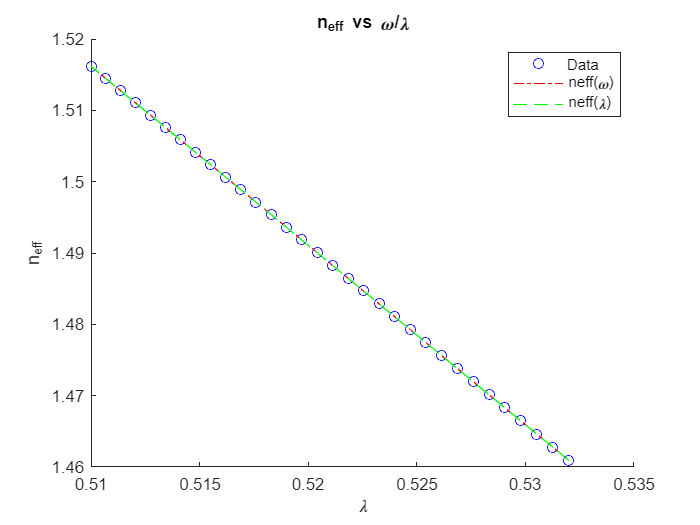

figure;
hold on
title("n_{eff} vs \omega/\lambda");
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
legend(["Data","neff(\omega)","neff(\lambda)"]);
xlabel("\lambda");
ylabel("n_{eff}");
hold off

#### Subfunctions (k, dw, Vg, d2w, D)

disp("Function k(ω):");

Function k(ω):


disp(wgSuperior.kwStr);

w.*(-2.362815545505330443363793346491e-283*w.^30+4.037432829134895234866074040568e-270*w.^29-4.537593124006705593524901324700e-260*w.^28+8.200551109962558970806336006070e-251*w.^27+4.745107850217131823882516952627e-241*w.^26-1.262166289472351573360078773401e-231*w.^25+4.482579067210485562550440960804e-222*w.^24-1.935860300577076177748197255701e-213*w.^23-2.180699981458150129134291216614e-202*w.^22+3.404636227209328630462981026724e-193*w.^21+1.825981451116238215337625545725e-184*w.^20+4.421587863018466678889833843689e-174*w.^19+2.500902763448172964048977771756e-164*w.^18-2.537223036406171215294657377651e-155*w.^17-4.312160254340629258952810788950e-145*w.^16-8.332848644891579672340028223781e-136*w.^15+1.987043676208591373863905607672e-126*w.^14+5.380015915835839896738763726356e-117*w.^13+2.235879944037515756607867684034e-107*w.^12-1.635704418799655005499420154011e-98*w.^11+5.095703999938492711084366682749e-88*w.^10-6.294835030315268890931866899683e-79*w.^9-1.00764483106314159709482746905

disp("Function dk(ω)/dω:");

Function dk(ω)/dω:


disp(wgSuperior.dkwdwStr);

(-2.362815545505330443363793346491e-283*w.^30*(31)+4.037432829134895234866074040568e-270*w.^29*(30)-4.537593124006705593524901324700e-260*w.^28*(29)+8.200551109962558970806336006070e-251*w.^27*(28)+4.745107850217131823882516952627e-241*w.^26*(27)-1.262166289472351573360078773401e-231*w.^25*(26)+4.482579067210485562550440960804e-222*w.^24*(25)-1.935860300577076177748197255701e-213*w.^23*(24)-2.180699981458150129134291216614e-202*w.^22*(23)+3.404636227209328630462981026724e-193*w.^21*(22)+1.825981451116238215337625545725e-184*w.^20*(21)+4.421587863018466678889833843689e-174*w.^19*(20)+2.500902763448172964048977771756e-164*w.^18*(19)-2.537223036406171215294657377651e-155*w.^17*(18)-4.312160254340629258952810788950e-145*w.^16*(17)-8.332848644891579672340028223781e-136*w.^15*(16)+1.987043676208591373863905607672e-126*w.^14*(15)+5.380015915835839896738763726356e-117*w.^13*(14)+2.235879944037515756607867684034e-107*w.^12*(13)-1.635704418799655005499420154011e-98*w.^11*(12)+5.09570399993849271

disp("Function Vg(ω):");

Function Vg(ω):


disp(wgSuperior.vgwStr);

(3*10^8)./(-2.362815545505330443363793346491e-283*w.^30*(31)+4.037432829134895234866074040568e-270*w.^29*(30)-4.537593124006705593524901324700e-260*w.^28*(29)+8.200551109962558970806336006070e-251*w.^27*(28)+4.745107850217131823882516952627e-241*w.^26*(27)-1.262166289472351573360078773401e-231*w.^25*(26)+4.482579067210485562550440960804e-222*w.^24*(25)-1.935860300577076177748197255701e-213*w.^23*(24)-2.180699981458150129134291216614e-202*w.^22*(23)+3.404636227209328630462981026724e-193*w.^21*(22)+1.825981451116238215337625545725e-184*w.^20*(21)+4.421587863018466678889833843689e-174*w.^19*(20)+2.500902763448172964048977771756e-164*w.^18*(19)-2.537223036406171215294657377651e-155*w.^17*(18)-4.312160254340629258952810788950e-145*w.^16*(17)-8.332848644891579672340028223781e-136*w.^15*(16)+1.987043676208591373863905607672e-126*w.^14*(15)+5.380015915835839896738763726356e-117*w.^13*(14)+2.235879944037515756607867684034e-107*w.^12*(13)-1.635704418799655005499420154011e-98*w.^11*(12)+5.0957039

disp("Function d2k(ω)/dω2:");

Function d2k(ω)/dω2:


disp(wgSuperior.d2kwdw2Str);

(-2.362815545505330443363793346491e-283*w.^29*(930)+4.037432829134895234866074040568e-270*w.^28*(870)-4.537593124006705593524901324700e-260*w.^27*(812)+8.200551109962558970806336006070e-251*w.^26*(756)+4.745107850217131823882516952627e-241*w.^25*(702)-1.262166289472351573360078773401e-231*w.^24*(650)+4.482579067210485562550440960804e-222*w.^23*(600)-1.935860300577076177748197255701e-213*w.^22*(552)-2.180699981458150129134291216614e-202*w.^21*(506)+3.404636227209328630462981026724e-193*w.^20*(462)+1.825981451116238215337625545725e-184*w.^19*(420)+4.421587863018466678889833843689e-174*w.^18*(380)+2.500902763448172964048977771756e-164*w.^17*(342)-2.537223036406171215294657377651e-155*w.^16*(306)-4.312160254340629258952810788950e-145*w.^15*(272)-8.332848644891579672340028223781e-136*w.^14*(240)+1.987043676208591373863905607672e-126*w.^13*(210)+5.380015915835839896738763726356e-117*w.^12*(182)+2.235879944037515756607867684034e-107*w.^11*(156)-1.635704418799655005499420154011e-98*w.^10*(132)

disp("Function D(ω):");

Function D(ω):


disp(wgSuperior.DwStr);

-(w.^2/(2*pi*3*10^8)).*((-2.362815545505330443363793346491e-283*w.^29*(930)+4.037432829134895234866074040568e-270*w.^28*(870)-4.537593124006705593524901324700e-260*w.^27*(812)+8.200551109962558970806336006070e-251*w.^26*(756)+4.745107850217131823882516952627e-241*w.^25*(702)-1.262166289472351573360078773401e-231*w.^24*(650)+4.482579067210485562550440960804e-222*w.^23*(600)-1.935860300577076177748197255701e-213*w.^22*(552)-2.180699981458150129134291216614e-202*w.^21*(506)+3.404636227209328630462981026724e-193*w.^20*(462)+1.825981451116238215337625545725e-184*w.^19*(420)+4.421587863018466678889833843689e-174*w.^18*(380)+2.500902763448172964048977771756e-164*w.^17*(342)-2.537223036406171215294657377651e-155*w.^16*(306)-4.312160254340629258952810788950e-145*w.^15*(272)-8.332848644891579672340028223781e-136*w.^14*(240)+1.987043676208591373863905607672e-126*w.^13*(210)+5.380015915835839896738763726356e-117*w.^12*(182)+2.235879944037515756607867684034e-107*w.^11*(156)-1.6357044187996550054994

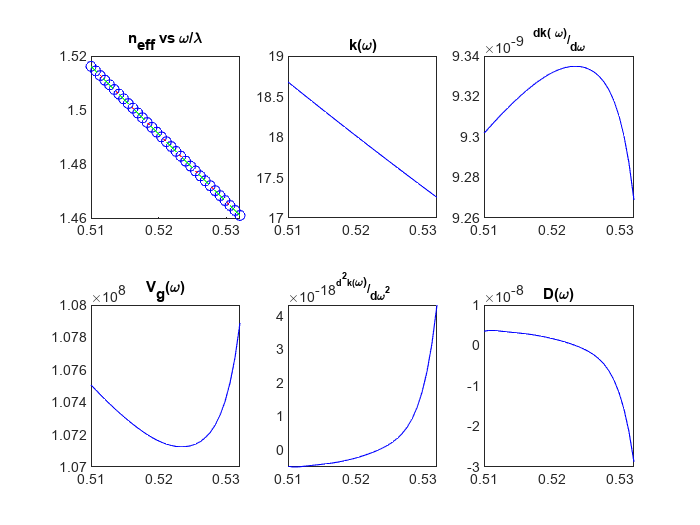

subplot(2,3,1);
plot(l,neff,'bo',l,wgSuperior.neffwFun(w),'r-.',l,wgSuperior.nefflFun(l),'g--');
title("n_{eff} vs \omega/\lambda");
subplot(2,3,2);
plot(l,wgSuperior.kwFun(w),'b');
title("k(\omega)");
subplot(2,3,3);
plot(l,wgSuperior.dkwdwFun(w),'b');
title("^{dk(\omega)}/_{d\omega}");
subplot(2,3,4);
plot(l,wgSuperior.vgwFun(w),'b');
title("V_g(\omega)");
subplot(2,3,5);
plot(l,wgSuperior.d2kwdw2Fun(w),'b');
title("^{d^2k(\omega)}/_{d\omega^2}");
subplot(2,3,6);
plot(l,wgSuperior.DwFun(w),'b');
title("D(\omega)");

##  Load Waveguide Simple:

 
file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
file = sprintf(Superior,sXs(sel),sYs(sel),mode);
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);

## K's comparing

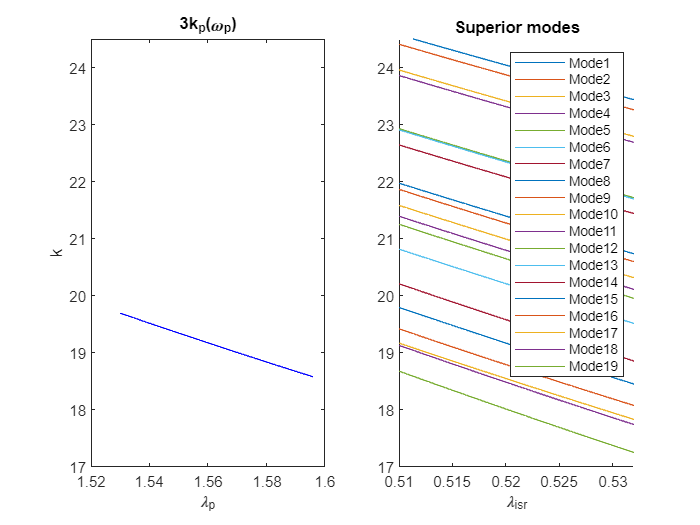

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
l = wgFundamental.lambdaData;
w = wgFundamental.omegaData;
neff = wgFundamental.neffData;
figure;
subplot(1,2,1)
plot(l,wgFundamental.kwFun(w).*3,'b');
leg = {};
title("3k_p(\omega_p)"); xlabel("\lambda_p"); ylabel("k");
ylim([17 24.5]);
subplot(1,2,2)
hold on
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    l = wgSuperior.lambdaData;
    w = wgSuperior.omegaData;
    plot(l,wgSuperior.kwFun(w));
    leg(end+1) = {"Mode"'+num2str(i)};
end
legend(leg);
ylim([17 24.5]);
title("Superior modes"); xlabel("\lambda_{isr}");
hold off

## Find degenerate photon that allow momentum and energy conservation

size=50;

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lp = linspace(lpLim(1),lpLim(2),size);
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

figure
hold on

dk0s = [];

for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14

    dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

    if(min(dk)<=0 && max(dk)>=0)
        dk0s = [dk0s i];
    end

    plot(lp,dk);
    leg(end+1) = {"Mode"'+num2str(i)};
end

if ~isequal(dk0s,[])
    strDk0s = sprintf('Modo %i,',dk0s);
    strDk0s = "Modos con dK=0: "+strDk0s(1:end-1);
else
    strDk0s = "Ningun modo con dK=0";
end

disp(strDk0s)

Modos con dK=0: Modo 15


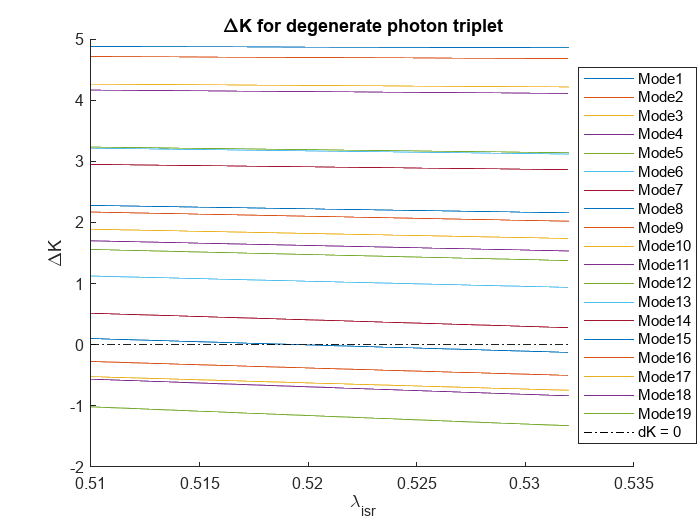


plot([lpLim(1),lpLim(2)],[0,0],'k-.')
leg(end+1) = {"dK = 0"};

legend(leg);
title("\DeltaK for degenerate photon triplet");
ylabel("\DeltaK"); xlabel("\lambda_{isr}");

legend("Position", [0.8256,0.15841,0.16964,0.70952])

## Phase Matching

switch nmodes
    case 15
        m = 5;n = 3;
    case 9
        m = 3;n = 3;
    case 19
        m = 5;n = 4;
    case 12
        m = 4;n = 3;
end

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
li = 1.53;
size=50;

wp = linspace(2.*pi.*3.*10.^8./lpLim(1),2.*pi.*3.*10.^8./lpLim(2),size);
dw = linspace(1e8,-1e8,size);
[WP,DW] = meshgrid(wp,dw);
wi = (2.*pi.*3.*10.^8./li);
wr = DW+(WP-wi)/2;
ws = WP-wi-wr;

disp("Pump wavelength: "+num2str(lpLim(1))+"-"+num2str(lpLim(2)));

Pump wavelength: 0.51-0.532


disp("Photon wavelength: "+num2str(lphLim(1))+"-"+num2str(lphLim(2)));

Photon wavelength: 1.53-1.596


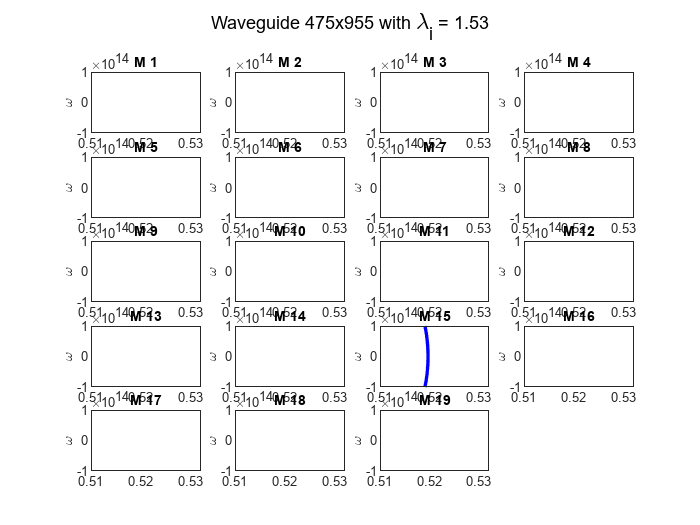

figure
for i = 1:nmodes
    file = sprintf(Superior,sXs(sel),sYs(sel),i);
    load(SuperiorPath+file);
    wgSuperior = waveguide(lambda,neff);
    %Nota w 10^8 es 10^14
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    subplot(m,n,i)
    contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
    title("M "+num2str(i));
    ylabel("\omega");
end
sgtitle("Waveguide "+num2str(sXs(sel))+"x"+num2str(sYs(sel))+" with \lambda_i = "+num2str(li))